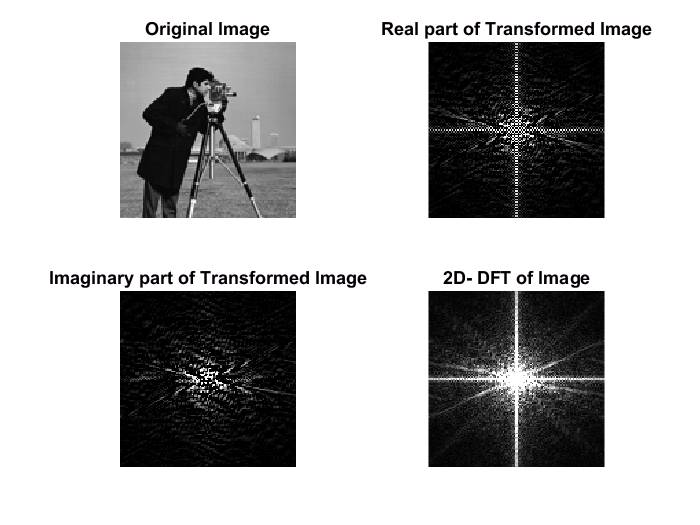

clear all
Img=double(imresize(imread('cameraman.tif'),0.5)); 
[Img_M, Img_N] = size(Img);
Output=zeros(Img_M,Img_N);
SumOutner = 0;
%%Centralized 2D Discrete Fourier Transform
[nx,ny]=ndgrid([0:Img_M-1]-(Img_M-1)/2,[0:Img_N-1]-(Img_N-1)/2 );
du=1;
 for u = [0:Img_M-1]-(Img_M-1)/2
     dv=1;
    for v = [0:Img_N-1]-(Img_N-1)/2  
        SumOutner=sum(sum(Img.*exp(-1i*2*3.1416*(u*nx/Img_M+v*ny/Img_N))));
        Output(du,dv) = SumOutner;
        dv=dv+1;
    end
    du=du+1;
 end
%%Calculate Spectrum and show
figure(1);
subplot(2,2,1);
imshow(imresize(imread('cameraman.tif'),0.5)); %Original Image 
title('Original Image');

subplot(2,2,4);
imshow(uint8(abs(Output)/60)); %Image after 2D Dft
title('2D- DFT of Image');

subplot(2,2,3);
imshow(uint8(imag((Output)/60))); %Imaginary Part
title('Imaginary part of Transformed Image');
subplot(2,2,2);
imshow(uint8(real((Output)/60))); %Real part
title('Real part of Transformed Image');